clc
clear
freq = 1/333;
m = 0.35;
names = ["nosex", "nosey", "nosez", "tailx", "taily", "tailz", "leftx", "lefty", "leftz", "rightx",...
    "righty", "rightz", "midx", "midy", "midz", "gx", "gy", "gz", "ax", "ay", "az"];

data = struct;
for i = [1,2,3,4]
    data.("a"+i) = readtable(i+"_complete_data.csv");
    data.("a"+i).Properties.VariableNames = names;
    
    diff_Z = data.("a"+i).tailz - data.("a"+i).midz;
    diff_Y = data.("a"+i).taily - data.("a"+i).midy;
    diff_X = data.("a"+i).tailx - data.("a"+i).midx;
    data.("a"+i).pitch = atand(diff_Z./diff_Y);
    data.("a"+i).yaw = atand(diff_Y./diff_X);
    
    diff_Z = data.("a"+i).leftz - data.("a"+i).rightz;
    diff_Y = data.("a"+i).lefty - data.("a"+i).righty;
    diff_X = data.("a"+i).leftx - data.("a"+i).rightx;
    data.("a"+i).roll = atand( diff_Z./diff_X);
    
    data.("a"+i).t = (freq:freq:(freq)*length(data.("a"+i).gy))';
    
    data.("a"+i).vx = [0; diff(0.5 * (data.("a"+i).midx + data.("a"+i).tailx)) ./ diff(data.("a"+i).t) * 1e-3];
    data.("a"+i).vy = [0; diff(0.5 * (data.("a"+i).midy + data.("a"+i).taily)) ./ diff(data.("a"+i).t) * 1e-3];
    data.("a"+i).vz = [0; diff(0.5 * (data.("a"+i).midz + data.("a"+i).tailz)) ./ diff(data.("a"+i).t) * 1e-3];
    data.("a"+i).v = smooth(vecnorm([data.("a"+i).vx, data.("a"+i).vy, data.("a"+i).vz]')',10, 'sgolay');
    
    data.("a"+i).glide_angle = smooth(atand(data.("a"+i).vz./data.("a"+i).vy),40, 'sgolay');
    data.("a"+i).AoA = data.("a"+i).pitch - data.("a"+i).glide_angle;
    
    data.("a"+i).a_x = ( data.("a"+i).az .* cosd(data.("a"+i).glide_angle) + data.("a"+i).ay) ./ (cosd(data.("a"+i).glide_angle) .* cosd(data.("a"+i).glide_angle) - sind(data.("a"+i).glide_angle));
    data.("a"+i).a_y = ( data.("a"+i).ay + data.("a"+i).a_x .* sind(data.("a"+i).glide_angle) )./cosd(data.("a"+i).glide_angle);
    
    data.("a"+i).lift = smooth(data.("a"+i).t, data.("a"+i).a_x, 20, 'sgolay')*m;
    data.("a"+i).drag = smooth(data.("a"+i).t, data.("a"+i).a_y, 20, 'sgolay')*m;
end

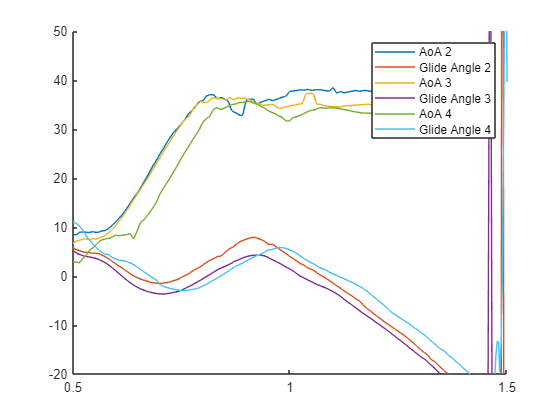

clf
hold on
for i = [2,3,4]
    d = data.("a"+i);
    plot(d.t, d.AoA, 'DisplayName',"AoA "+i);
    plot(d.t, d.glide_angle, 'DisplayName', "Glide Angle "+i)
end
hold off
legend
ylim([-20,50])
xlim([0.5,1.5])

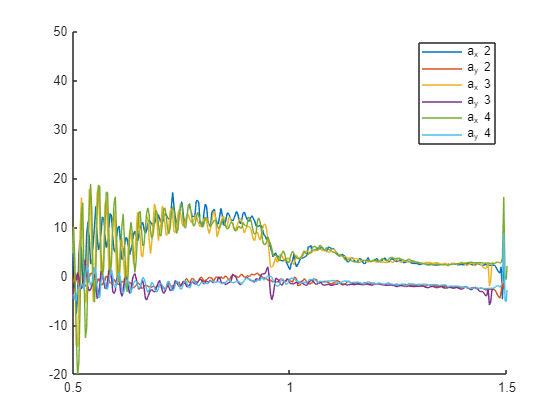

clf
hold on
for i = [2,3,4]
    d = data.("a"+i);
    plot(d.t, d.a_x, 'DisplayName',"a_x "+i);
    plot(d.t, d.a_y, 'DisplayName', "a_y "+i)
end
hold off
legend
ylim([-20,50])
xlim([0.5,1.5])

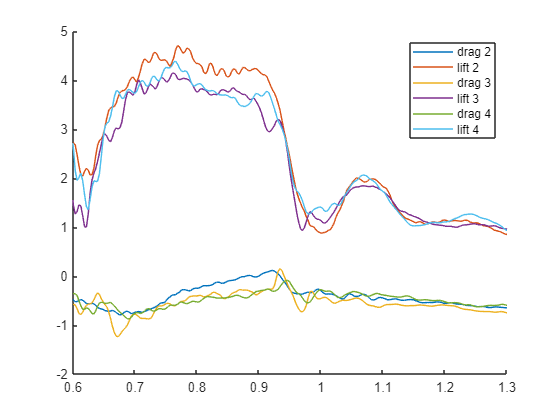

clf
hold on
for i = [2,3,4]
    d = data.("a"+i);
    plot(d.t, d.drag, 'DisplayName',"drag "+i);
    plot(d.t, d.lift, 'DisplayName',"lift "+i);
    %plot(d.t, d.lift./d.drag)
end
hold off
legend
xlim([0.6,1.3])

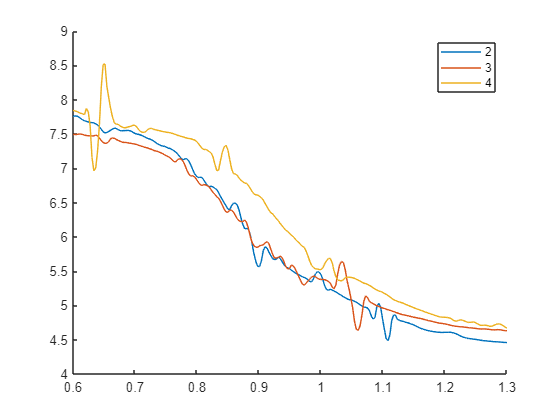

clf
hold on
for i = [2,3,4]
    d = data.("a"+i);
    plot(d.t, d.v,'DisplayName',""+i);
end
hold off
legend
xlim([0.6,1.3])

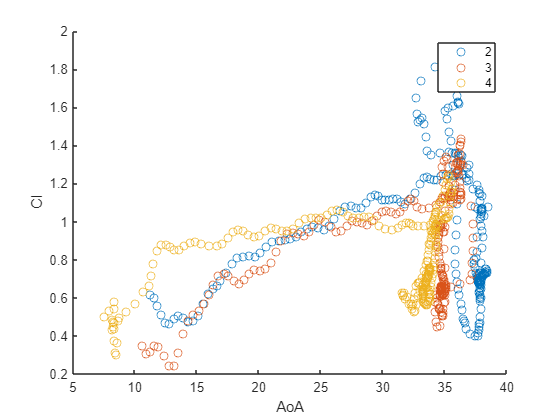

clf
hold on
A = 0.15*0.8;
store = [];
for i = [2,3,4]
    d = data.("a"+i);
    d = d(d.t>0.6, :);
    d = d(d.t<1.3, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    scatter(d.AoA, Cl, 'DisplayName',""+i)
end
hold off
legend
xlabel("AoA")
ylabel("Cl")

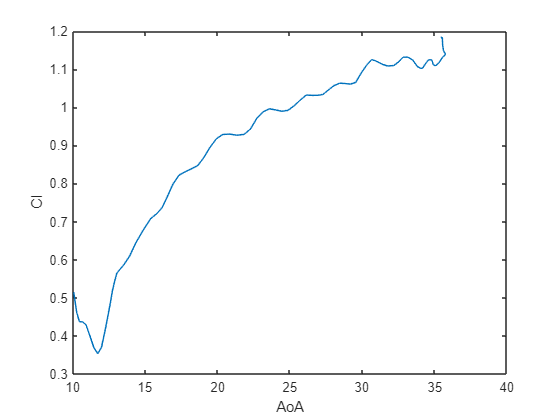

clf
A = 0.15*0.8;
storecl = [];
storeaoa = [];
for i = [2,3,4]
    d = data.("a"+i);
    d = d(d.t>0.6, :);
    d = d(d.t<0.85, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    storecl(:, i) = Cl;
    storeaoa(:, i) = d.AoA;
end

plot(mean(storeaoa(:, 2:4),2), mean(storecl(:, 2:4),2))
xlabel("AoA")
ylabel("Cl")

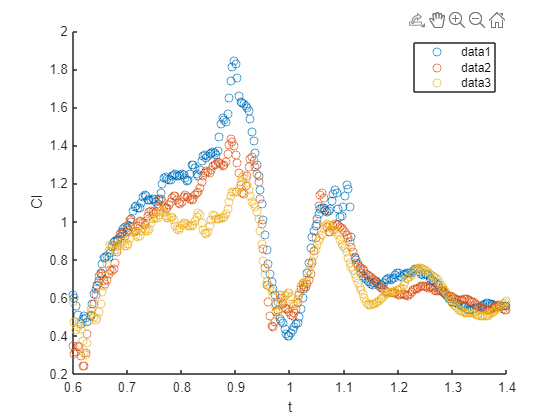

clf
hold on
A = 0.15*0.8;
for i = [2,3,4]
    d = data.("a"+i);
    d = d(d.t>0.6, :);
    d = d(d.t<1.4, :);
    Cl = (2 .* d.lift) ./ (1.225 .* d.v.^2 .*A);
    scatter(d.t, Cl);
end
hold off
legend
xlabel("t")
ylabel("Cl")